# Train Hardware Soft Robot

clear all; clear vars; close all; clc;
warning('off','all')

% Number of observables
numObs = 15;
% Define dimension of modes
SSMDim = 6; hSSMDim = SSMDim/2;
load obsDecayDataC

## Visualize Training Data

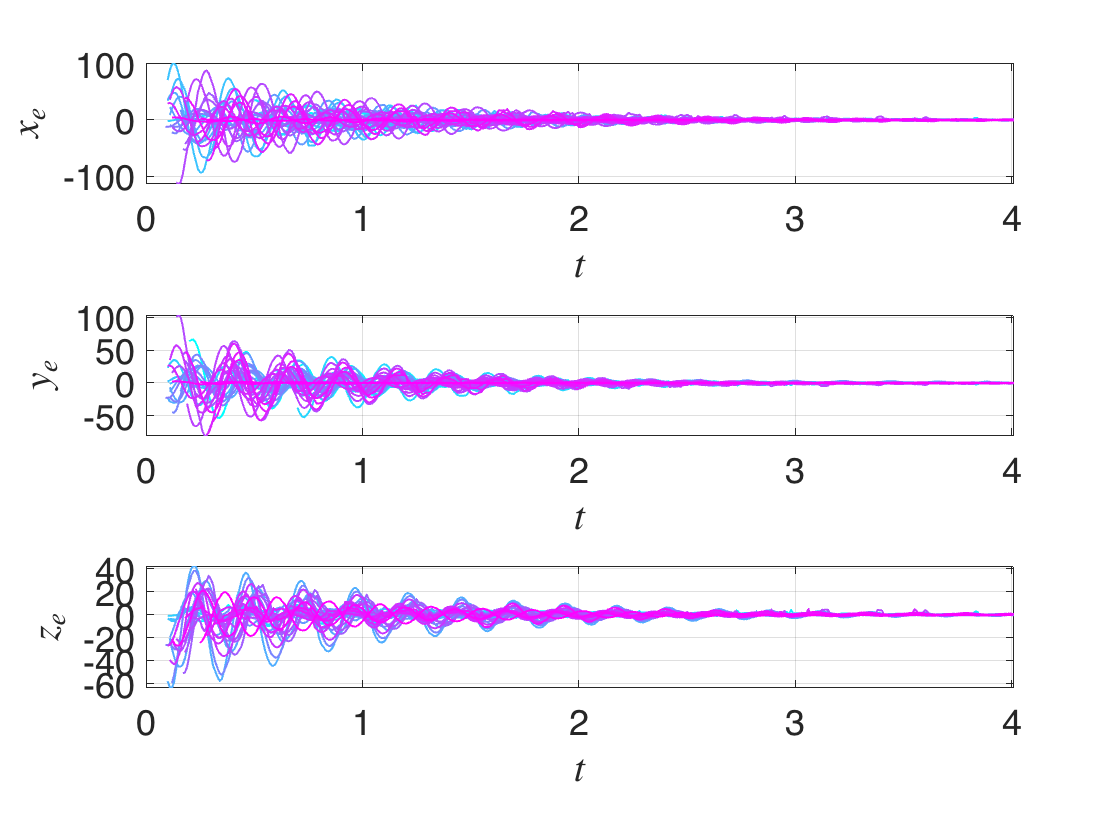

trajs = [13, 14, 15];
numCoord = length(trajs);
customFigure('subPlot',[numCoord 1]);
labels = ["$x_a$", "$y_a$", "$z_a$", ...
    "$x_b$", "$y_b$", "$z_b$", ...
    "$x_c$", "$y_c$", "$z_c$", ...
    "$x_d$", "$y_d$", "$z_d$", ...
    "$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:numCoord
    subplot(numCoord,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(trajs(iPlt)),'Interpreter','latex');
end

for iTraj = 1:size(oData, 1)
    for iObs = 1:numCoord
        subplot(numCoord,1,iObs);
        plot(oData{iTraj,1},oData{iTraj,2}(trajs(iObs),:),'Linewidth',1)
    end
end

Consider only the tip positions, neglect other sensor data in this script.

tipData = oData;
for iTraj = 1:size(oData, 1)
    tipData{iTraj,2} = oData{iTraj,2}(trajs,:);
end

Perform delay-embedding. As observables for the model, we consider the current tip position data as well as past measurements (no future ones) of the tip position data. For this case (we only consider the tip), we have a minimum of `4` delays, which is augmented by the `overEmbed` variable, so that the number of total delays is `4+overEmbed`. We also do some cutting, but it is not necessary in this current case.

%overEmbed = 21;
overEmbed = 0;
[yData, opts_embd] = coordinatesEmbeddingControl(tipData, SSMDim, 'OverEmbedding', overEmbed);

The 15 embedding coordinates consist of the 3 measured states and their 4 time-delayed measurements.


embedDim = size(yData{1,2},1);
outdofs = [embedDim-2 embedDim-1 embedDim];
sliceInt = [0.01, Inf];
yDataTrunc = sliceTrajectories(yData, sliceInt);

PCA is still useful in the delay-embeeded space, as the number of modes explaining most of the data should be the dimension of the SSM. Indeed, we get it as more than 90% of variance is explained by the first six PCA modes.

disp('PCA')

PCA


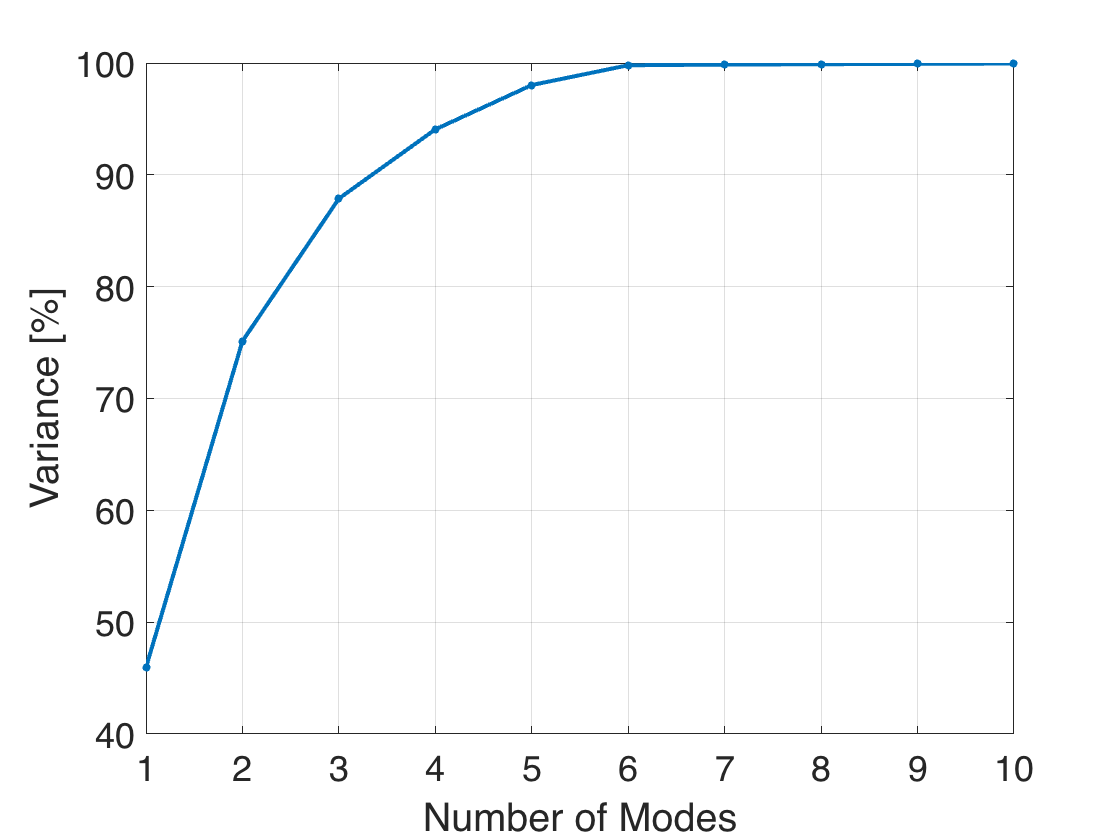

Xsnapshots = cat(2,yDataTrunc{:,2});
% Perform SVD on displacement field
[V,S,~] = svd(Xsnapshots, 0);
% Note we assume data centered around the origin, which is the
% fixed point of our system
customFigure;
maxModesPlot = 10;
l2vals = diag(S).^2;
plot(1:length(l2vals),cumsum(l2vals)/sum(l2vals)*100,'.-','Linewidth',2,'MarkerSize',12)
xlabel('Number of Modes');
ylabel('Variance [%]');
xlim([1 maxModesPlot])
set(gca,'XTick',[1:1:maxModesPlot])


Vde = V(:,1:SSMDim);
% Set reduced-coordinates as PCA projection to the first six modes
etaDataTrunc = yDataTrunc;
for iTraj = 1:size(oData, 1)
    etaDataTrunc{iTraj,2} = transpose(Vde)*yDataTrunc{iTraj,2};
end

% Set test and train trajectories
indTest = [5 15 21 32 38];
indTrain = setdiff(1:size(oData, 1),indTest);

## Geometry

Manifold fitting with prescribed graph. Higher orders tend to overfit.

SSMOrder = 3;
if SSMOrder == 1
    % Need to recompute as the columns of Vde might change in order
    IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder);
    Vde = IMInfo.parametrization.tangentSpaceAtOrigin;
    etaDataTrunc = yDataTrunc;
    for iTraj = 1:size(oData, 1)
        etaDataTrunc{iTraj,2} = transpose(Vde)*yDataTrunc{iTraj,2};
    end
else
    IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder,'reducedCoordinates',etaDataTrunc(indTrain,:));
    IMInfo.chart.map = @(x) transpose(Vde)*x;
end

Evaluate learning of geometry.

%% Trajectory lifting requires reduced coordinates (ensures y is on manifold, 
% hence yRec =/= yDataTrunc)
disp('Results of geometry fit:')

Results of geometry fit:


yRec = liftTrajectories(IMInfo, etaDataTrunc);
normedTrajDist = computeTrajectoryErrors(yRec, yDataTrunc);
meanErrorGeoTrain = mean(normedTrajDist(indTrain))*100

meanErrorGeoTrain = 0.7927

meanErrorGeoTest = mean(normedTrajDist(indTest))*100

meanErrorGeoTest = 0.7303

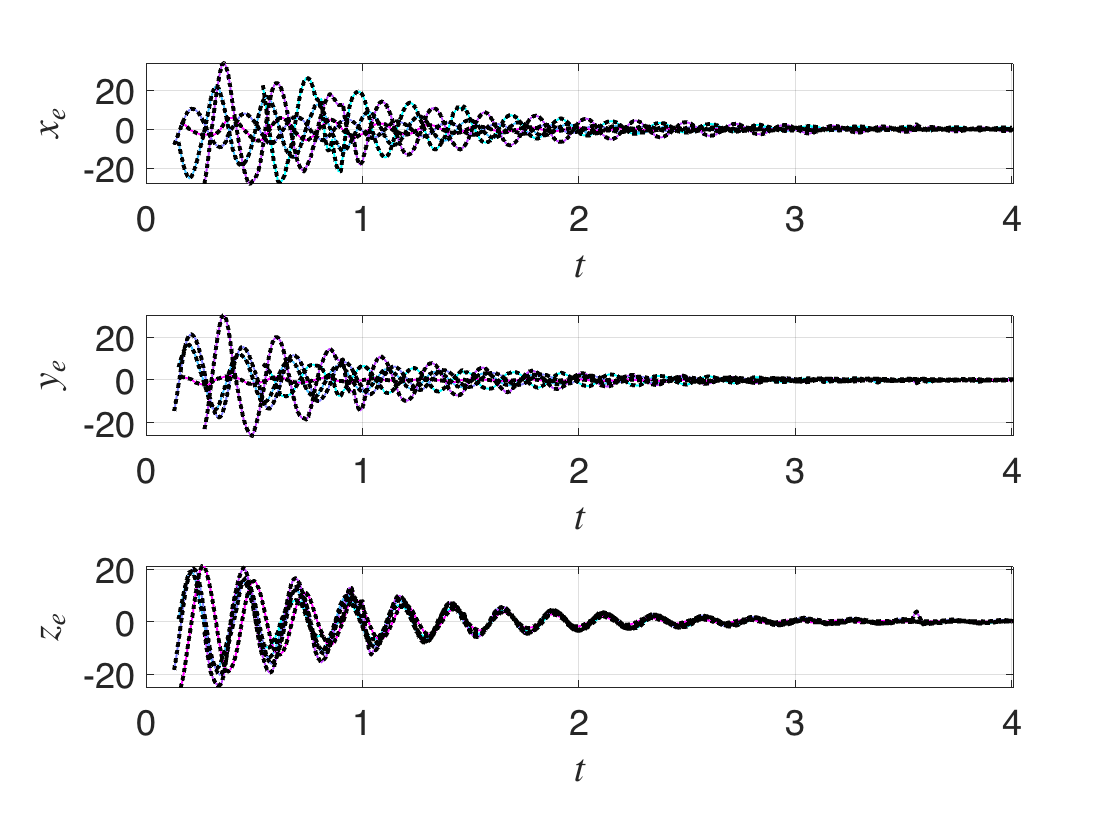


% Testing mapping function
xData = yData;
for iTraj = 1:size(yData, 1)
    xData{iTraj, 2} = IMInfo.chart.map(yData{iTraj, 2});
end
yDataRemapped = liftTrajectories(IMInfo, xData);

% Plot test data
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        %plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
        plot(yDataRemapped{indTest(iTraj),1},yDataRemapped{indTest(iTraj),2}(outdofs(iObs),:),'Linewidth',1)

    end
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yRec{indTest(iTraj),1},yRec{indTest(iTraj),2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end

## Reduced dynamics

Cubic order dynamics halves the trajectory error of linear dynamics. The `Map` case seems more accurate than the `Flow` one.

ROMOrder = 3;
RDInfo = IMDynamicsFlow(etaDataTrunc(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'default');

Estimation of the reduced dynamics...  Done. 


RDInfo.eigenvaluesLinPartFlow(1:3)

ans =   -0.8583 +25.8497i
  -1.1318 +26.2102i
  -0.9418 +26.6781i


Rauton = RDInfo.reducedDynamics.map

Rauton = function_handle with value:
    @(x)W_r*phi(x)

Evaluate learning of reduced dynamics.

disp('Errors for the dynamics on reduced-coordinates:')

Errors for the dynamics on reduced-coordinates:


etaRec = advectRD(RDInfo, etaDataTrunc);
normedTrajDist = computeTrajectoryErrors(etaRec, etaDataTrunc);
meanErrorDynTrain = mean(normedTrajDist(indTrain))*100

meanErrorDynTrain = Inf

meanErrorDynTest = mean(normedTrajDist(indTest))*100

meanErrorDynTest = 10.3466

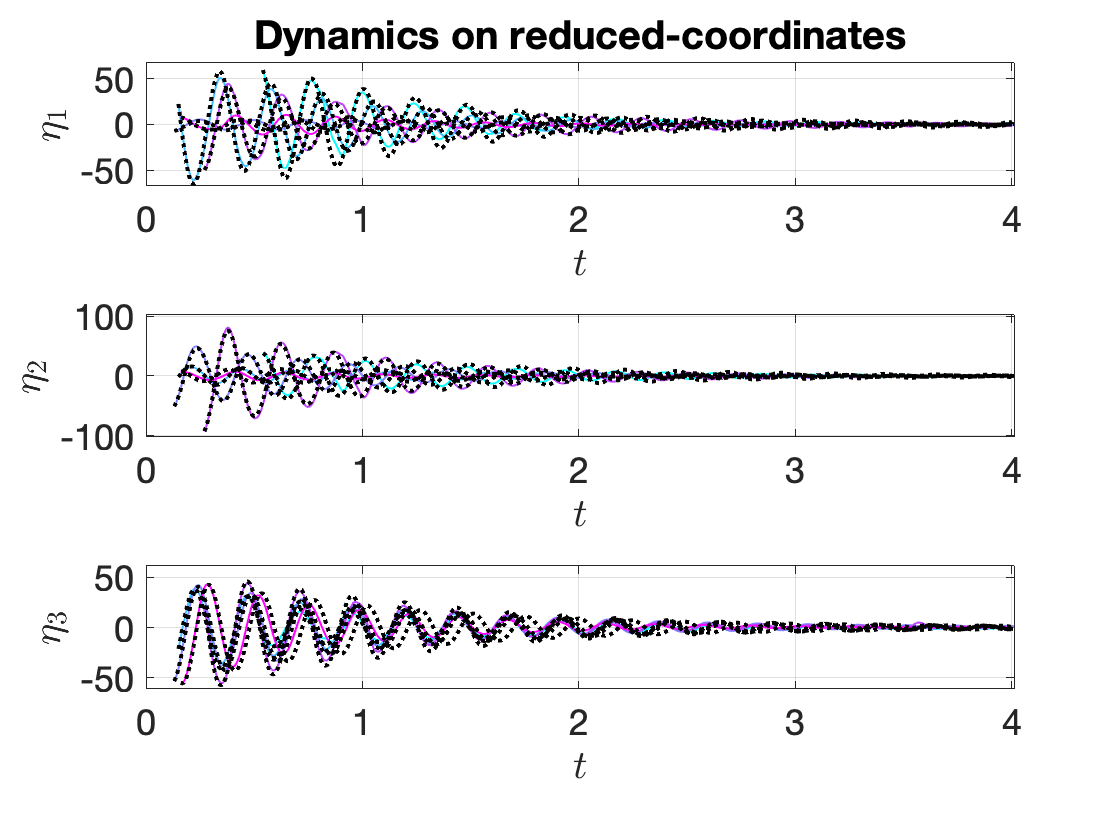


customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1); title('Dynamics on reduced-coordinates')
labels = ["$\eta_1$", "$\eta_2$", "$\eta_3$"];
for iPlt = 1:hSSMDim
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
yLimits = [0 0 0];
for iTraj = 1:length(indTest)
    for iObs = 1:hSSMDim
        subplot(numCoord,1,iObs);
        plot(etaDataTrunc{indTest(iTraj),1},etaDataTrunc{indTest(iTraj),2}(iObs,:),'Linewidth',1)
        yLimits(iObs) = max([max(abs(etaDataTrunc{indTest(iTraj),2}(iObs,:))) yLimits(iObs)]);
        ylim([-1 1]*1.1*yLimits(iObs))
    end
end

for iTraj = 1:length(indTest)
    for iObs = 1:hSSMDim
        subplot(numCoord,1,iObs);
        plot(etaRec{indTest(iTraj),1},etaRec{indTest(iTraj),2}(iObs,:),'k:','Linewidth',2)
    end
end

Visualize performance with real observables.

disp('Errors for the reduced-order model (geometry & dynamics):')

Errors for the reduced-order model (geometry & dynamics):


yRec = liftTrajectories(IMInfo, etaRec);
normedTrajDist = computeTrajectoryErrors(yRec, yDataTrunc);
meanErrorROMTrain = mean(normedTrajDist(indTrain))*100

meanErrorROMTrain = Inf

meanErrorROMTest = mean(normedTrajDist(indTest))*100

meanErrorROMTest = 10.4384

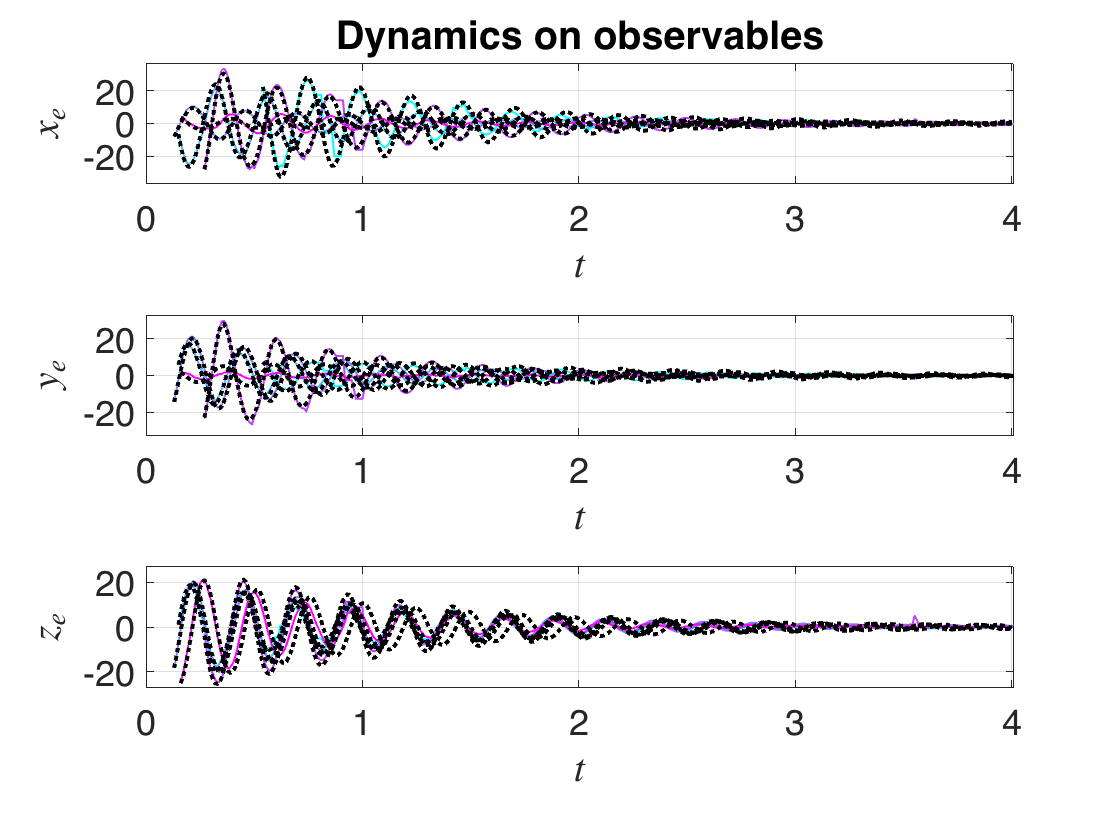


customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1); title('Dynamics on observables')
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
yLimits = [0 0 0];
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yDataTrunc{indTest(iTraj),1},yDataTrunc{indTest(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
        yLimits(iObs) = max([max(abs(yDataTrunc{indTest(iTraj),2}(outdofs(iObs),:))) yLimits(iObs)]);
        ylim([-1 1]*1.1*yLimits(iObs))
    end
end

for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yRec{indTest(iTraj),1},yRec{indTest(iTraj),2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end
hold off

Here we plot the 3 best and 3 worst predictions

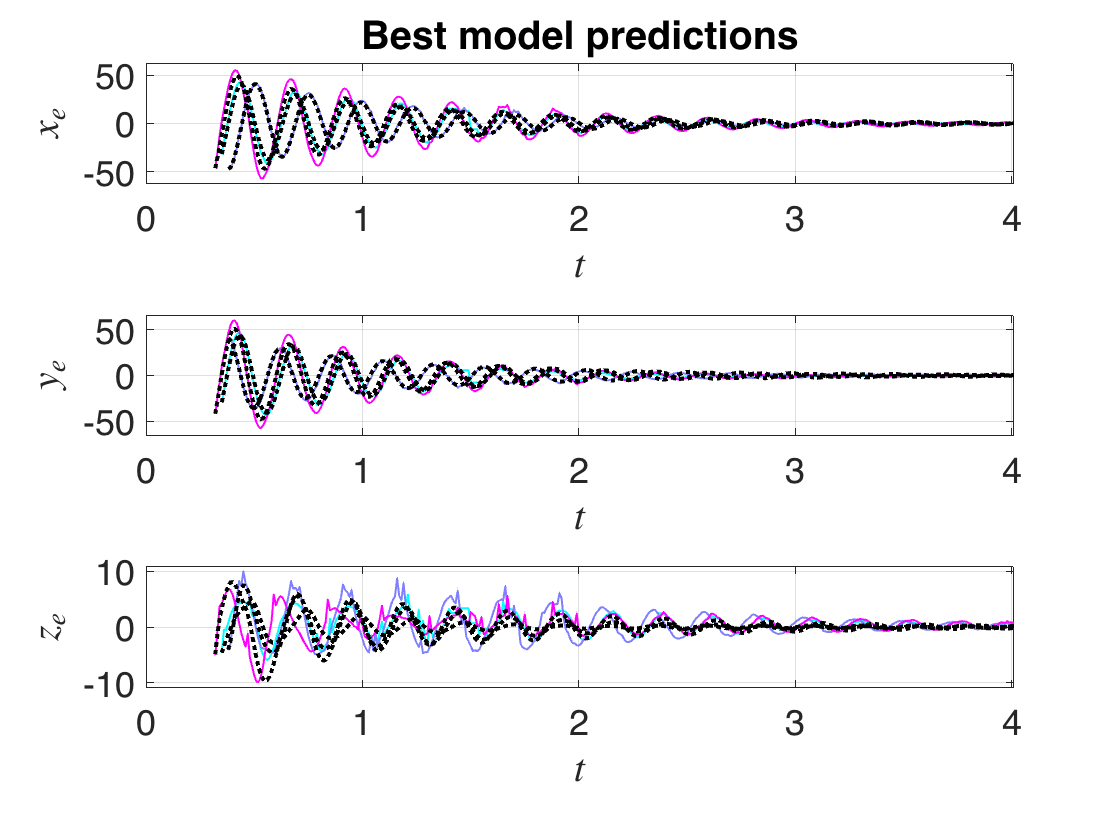

[~,ranks] = sort(normedTrajDist,'ascend');
indAct = ranks(1:3); % Best
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1); title('Best model predictions')
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indAct)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
yLimits = [0 0 0];
for iTraj = 1:length(indAct)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yDataTrunc{indAct(iTraj),1},yDataTrunc{indAct(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
        yLimits(iObs) = max([max(abs(yDataTrunc{indAct(iTraj),2}(outdofs(iObs),:))) yLimits(iObs)]);
        ylim([-1 1]*1.1*yLimits(iObs))
    end
end

for iTraj = 1:length(indAct)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yRec{indAct(iTraj),1},yRec{indAct(iTraj),2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end

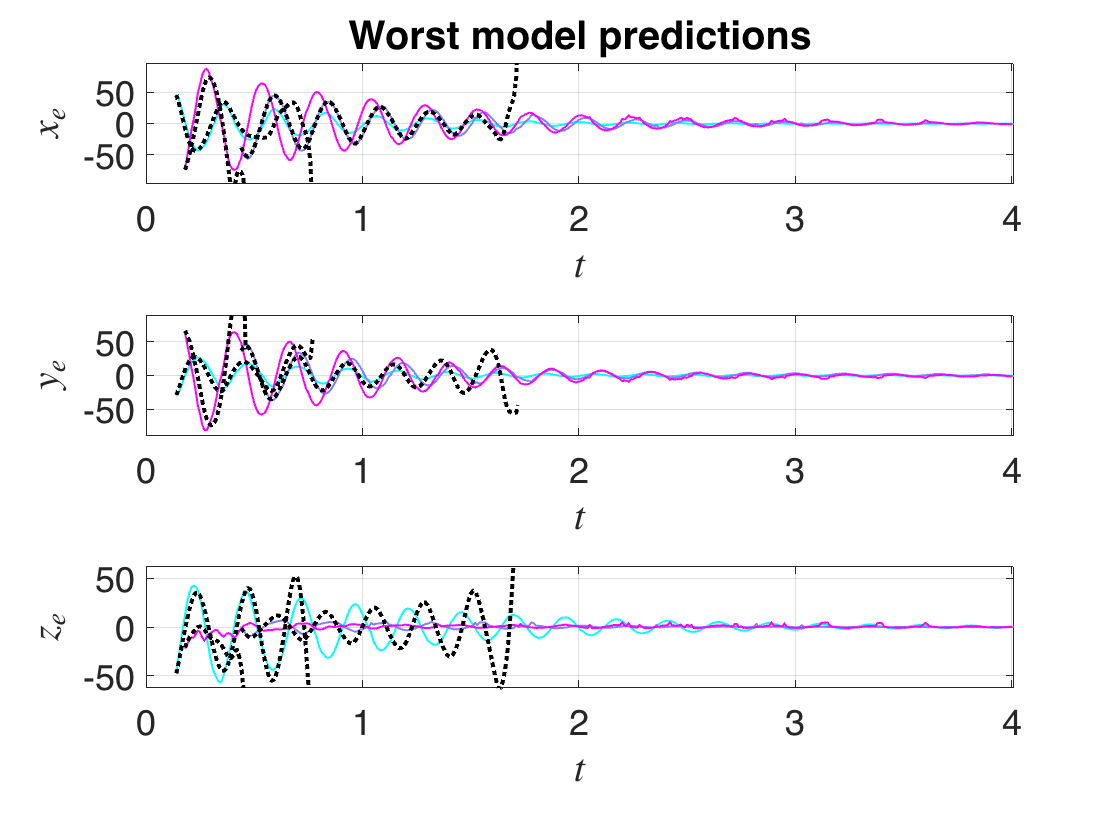


indAct = ranks(end-2:end); % Worst
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1); title('Worst model predictions')
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indAct)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
yLimits = [0 0 0];
for iTraj = 1:length(indAct)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yDataTrunc{indAct(iTraj),1},yDataTrunc{indAct(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
        yLimits(iObs) = max([max(abs(yDataTrunc{indAct(iTraj),2}(outdofs(iObs),:))) yLimits(iObs)]);
        ylim([-1 1]*1.1*yLimits(iObs))
    end
end

for iTraj = 1:length(indAct)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yRec{indAct(iTraj),1},yRec{indAct(iTraj),2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end

## Learn control matrix

% load koopman_data
% Consolidate data into standard var names and shift observation to origin
% z = y - y(:, end);
% zu{1,1} = t; zu{1,2} = z; 
% uCell{1,1} = t; uCell = u;

load koopman_data_figureEight
zu{1,1} = t; zu{1,2} = y - y(:, end); uCell{1,1} = t; uCell{1,2} = u;
% zu{2,1} = t; zu{2,2} = y - y_eq'; uCell{2,1} = t; uCell{2,2} = u;

% Project observables then lift (if required)
[Yu, yu_opts_embd] = coordinatesEmbeddingControl(zu, SSMDim, 'OverEmbedding', overEmbed);

The 15 embedding coordinates consist of the 3 measured states and their 4 time-delayed measurements.


[Udelay, ~] = coordinatesEmbeddingControl(uCell, SSMDim, 'OverEmbedding', overEmbed, 'ndim', size(zu{1,2}, 1))

The 15 embedding coordinates consist of the 3 measured states and their 4 time-delayed measurements.


Udelay = 1×2 cell array
    {[0.0400 0.0500 0.0600 0.0699 0.0800 0.0900 0.1000 0.1099 0.1200 0.1299 0.1400 0.1499 0.1600 0.1700 0.1800 0.1900 0.2000 0.2100 0.2200 0.2300 0.2400 0.2500 0.2600 0.2699 0.2800 0.2900 0.3000 0.3100 0.3200 0.3299 0.3400 0.3500 0.3599 0.3699 0.3800 0.3900 0.4000 0.4099 0.4200 0.4300 0.4400 0.4500 0.4599 0.4699 0.4800 0.4900 0.5000 0.5099 0.5200 0.5300 0.5400 0.5500 0.5599 0.5700 0.5800 0.5899 0.5999 0.6100 0.6200 0.6300 0.6400 0.6500 0.6599 0.6700 0.6800 0.6900 0.7000 0.7099 0.7200 0.7300 0.7400 0.7500 0.7600 0.7700 0.7800 0.7900 0.7999 0.8100 0.8200 0.8299 0.8399 0.8499 0.8599 0.8699 0.8799 0.8900 0.9000 0.9099 0.9199 0.9300 0.9400 0.9500 0.9599 0.9700 0.9800 0.9900 0.9999 1.0100 1.0200 1.0299 1.0400 1.0499 1.0599 1.0699 1.0799 1.0900 1.0999 1.1099 1.1200 1.1299 1.1399 1.1500 1.1599 1.1699 1.1799 1.1900 1.1999 1.2100 1.2200 1.2300 1.2400 1.2500 1.2599 1.2700 1.2800 1.2901 1.3000 1.3099 1.3199 1.3300 1.3400 1.3500 1.3599 1.3700 1.3800 1.3900 1.4000 1.4099 1.42

uembedDim = size(Udelay{1,2},1);
udofs = [uembedDim-3, uembedDim-2 uembedDim-1 uembedDim];


YuData = []; UTrain = []; tTrain = [];
for iTraj = 1:size(Yu, 1)
    tStart = Yu{iTraj, 1}(1);
    [~, idxStart] = min( abs( zu{iTraj, 1}-tStart ) );
    
    % Concatenate times
    tcurrCenter = Yu{iTraj, 1} - Yu{iTraj, 1}(1);
    if isempty(tTrain)
        tcurrEnd = 0;
        tTrain = [tTrain, tcurrCenter];
    else
        tcurrEnd = tTrain(end); % End of previous time span
        tTrain = [tTrain, tcurrEnd + tcurrCenter(2:end)];
    end
    
    % Concatenate inputs
    UTrain = [UTrain, Udelay{iTraj,2}(udofs, :)];
    YuData = [YuData, Yu{iTraj,2}]; % No need to truncate (handled by coordsEmbedControl func)    
end

% Project lifted observation down to tangent space
xBarData = IMInfo.chart.map(YuData);

% Compute finite difference for data and truncate U to match dimensions
apprxOrd = 3;
[dXBarDt,xBarData,tTrain] = finiteTimeDifference(xBarData, tTrain, apprxOrd); % Truncates X_bar 3 places on each side
UTrain = UTrain(:, 1+apprxOrd:end-apprxOrd);

dXbarDt_aut = Rauton(xBarData); % Evaluate autonomous ROM dynamics for each Xbar

% Set options for ridgeRegression
varargin = {'R_PolyOrd', [3], 'style', 'default'};
nargin = 5;

L2 = 1 + 0 * exp(0*tTrain);

% Learn whole B matrix
[B_learn,l_opt,Err] = ridgeRegression(UTrain, dXBarDt - dXbarDt_aut, L2, [], 0);
R = @(t,x,u) Rauton(x) + B_learn*u;

**Validate Control model**

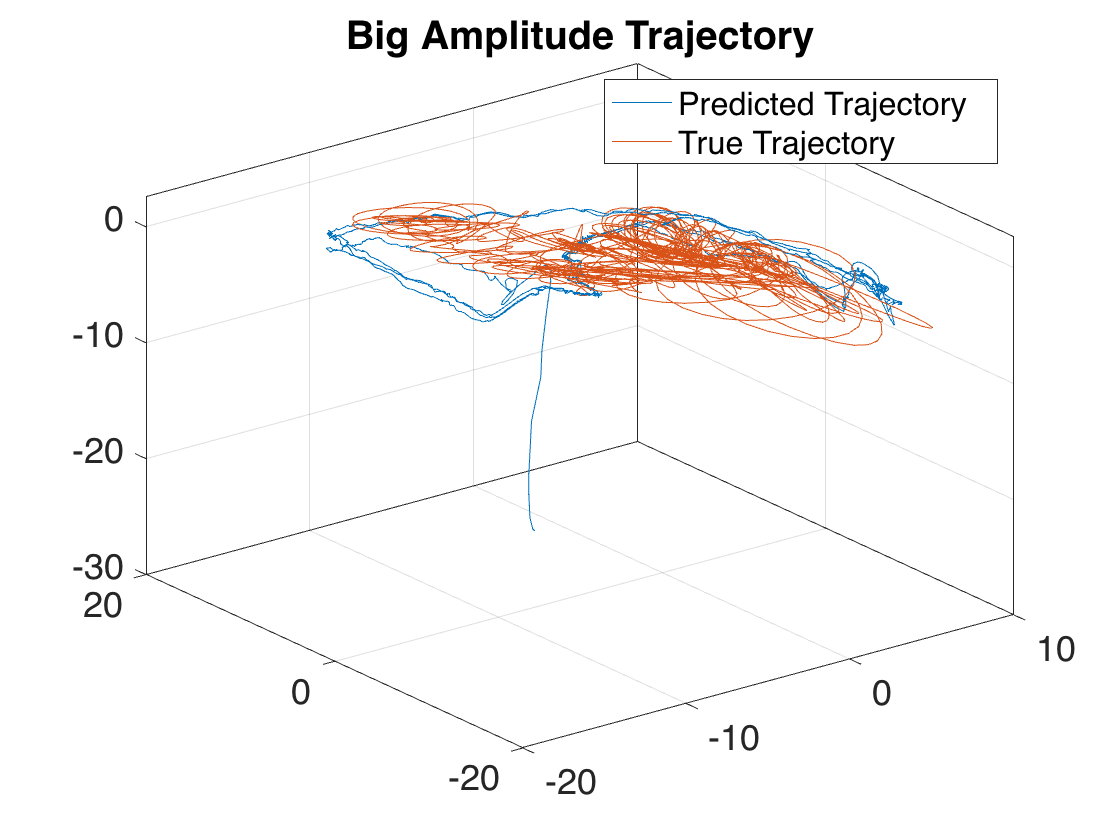

load koopman_data_figureEight
% load koopman_data
zTrue = y - y_eq';
tTrue = t;
uTrue = u'; % First dimension of interpolated value must be same size as t
uFun = @(t) transpose(interp1(tTrue, uTrue, t));
[tTraj,xTraj] = ode45(@(t,x) R(t,x,uFun(t)),tTrue,zeros(SSMDim,1)); % Assume we start at origin

xRecData = cell(1, 2); xRecData{1,1} = tTraj; xRecData{1,2} = xTraj';
yVal = liftTrajectories(IMInfo, xRecData);
zVal = yVal{1,2}(outdofs,:);

% Visualize the trajectory
customFigure; 
plot3(zTrue(1, :), zTrue(2, :), zTrue(3, :));
plot3(zVal(1, :), zVal(2, :), zVal(3, :));
legend('Predicted Trajectory', 'True Trajectory');
title('Big Amplitude Trajectory');
view(3);

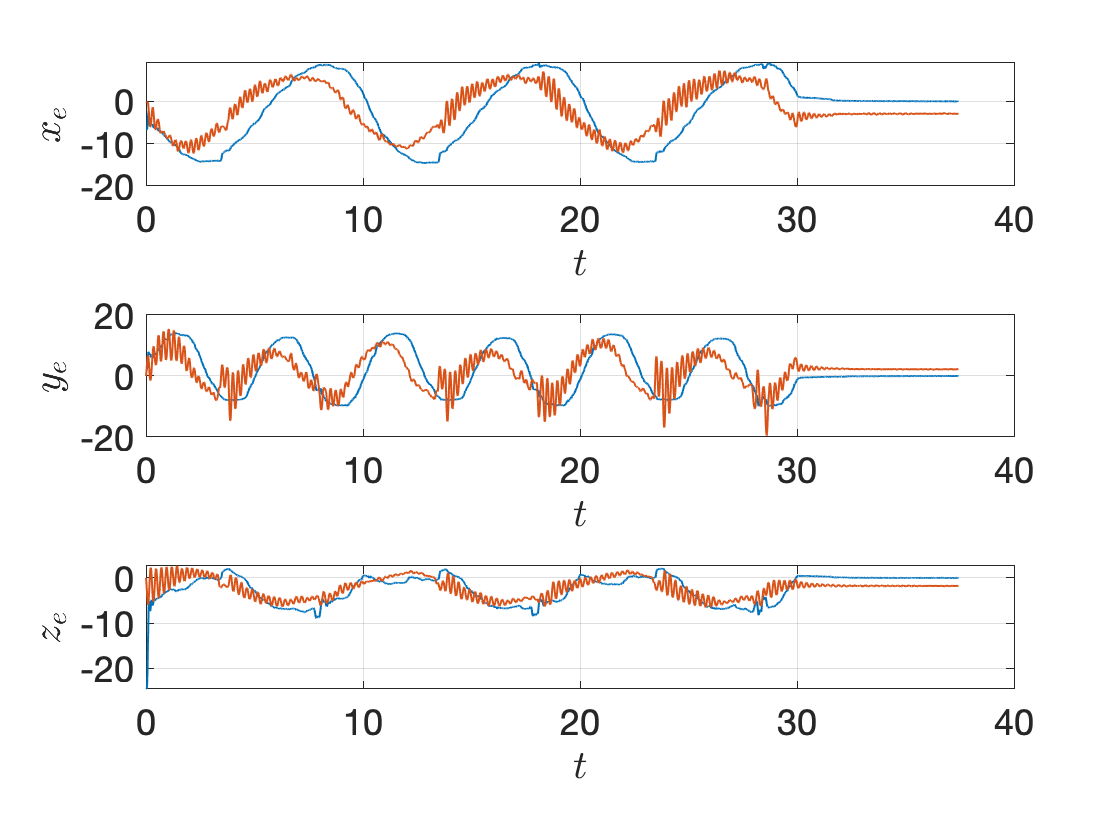


% Plot time series
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iObs = 1:length(outdofs)
    subplot(numCoord,1,iObs);
    plot(tTrue, zTrue(iObs, :),'Linewidth',1);
end
for iObs = 1:length(outdofs)
    subplot(numCoord,1,iObs);
    plot(tTrue, zVal(iObs, :),'Linewidth',1);
end

yTrue = coordinatesEmbeddingControl({tTrue, zTrue}, SSMDim, 'OverEmbedding', overEmbed);

The 15 embedding coordinates consist of the 3 measured states and their 4 time-delayed measurements.


yTrueInput = {yTrue{1,1}, IMInfo.chart.map(yTrue{1,2})};

yPred = coordinatesEmbeddingControl({tTrue, zVal}, SSMDim, 'OverEmbedding', overEmbed);

The 15 embedding coordinates consist of the 3 measured states and their 4 time-delayed measurements.


yPredInput = {yPred{1,1}, IMInfo.chart.map(yPred{1,2})};

normedTrajDist = computeTrajectoryErrors(yPredInput, yTrueInput);
meanErrorDynTrain = mean(normedTrajDist)*100

meanErrorDynTrain = 28.9387

meanErrorDynTest = mean(normedTrajDist)*100

meanErrorDynTest = 28.9387